# Component Gallery

close all;
clear;
clc;

## WithTableData

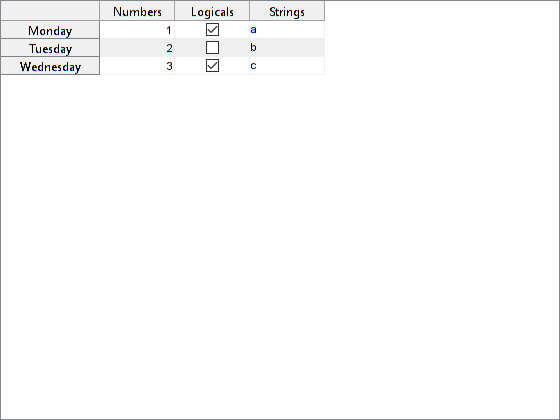

demoTable = table(...
    [1;2;3],...
    [true;false;true],...
    {'a';'b';'c'},...
    'VariableNames', {'Numbers', 'Logicals', 'Strings'},...
    'RowNames', {'Monday', 'Tuesday', 'Wednesday'} );
f = figure();
uiTable = uitable(...
    'Parent', f,...
    'Units', 'normalized',...
    'Position', [0 0 1 1] );
enhance( uiTable, 'fx.graphics.WithTableData' );
uiTable.TableData = demoTable;

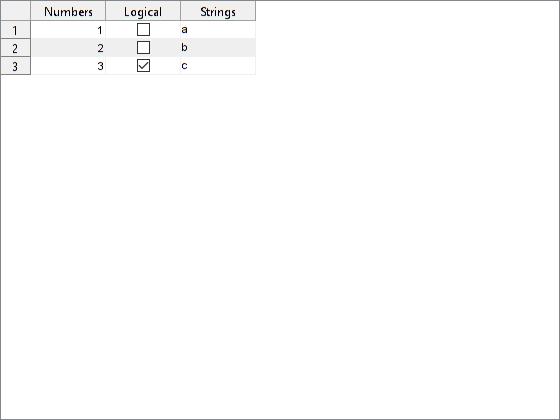

delete( uiTable );
uiTable = uitable(...
    'Parent', f,...
    'Units', 'normalized',...
    'Position', [0 0 1 1] );
enhance( uiTable, 'fx.graphics.WithTableData' );
uiTable.Data = {1 false 'a';2 false 'b';3 true 'c'};
uiTable.ColumnName = {'Numbers', 'Logical', 'Strings'};

demoTable = uiTable.TableData;
disp( demoTable );

         Numbers    Logical    Strings
         _______    _______    _______

    1    1          false      'a'    
    2    2          false      'b'    
    3    3          true       'c'    



delete( f );

## WithBetterColumnWidth

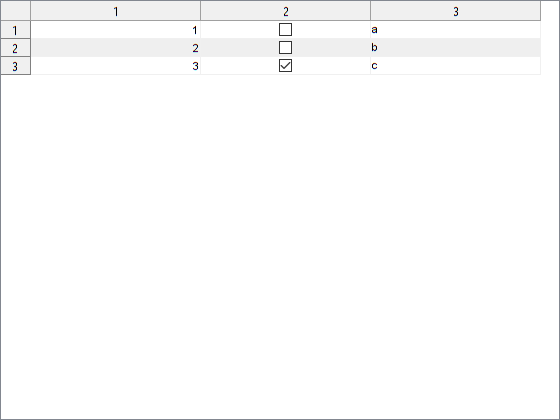

f = figure();
uiTable = uitable(...
    'Parent', f,...
    'Units', 'normalized',...
    'Position', [0 0 1 1] );
enhance( uiTable, 'fx.graphics.WithVariableColumnWidths' );
uiTable.Data = {1 false 'a';2 false 'b';3 true 'c'};

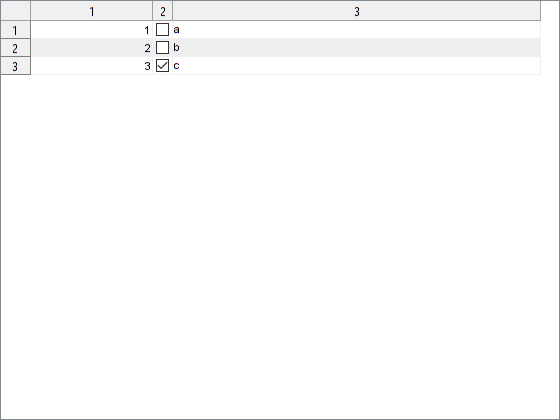

uiTable.VariableColumnWidths = [-1 20 -3];

delete(f);

## WithImage

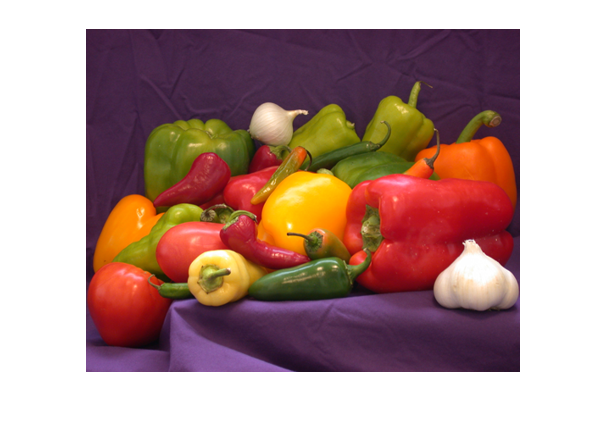

imagePath = 'C:\Program Files\MATLAB\R2017b\toolbox\matlab\imagesci\peppers.png';
f = figure;
ax = axes( ...
    'Parent', f );

enhance( ax, 'fx.graphics.WithImage' );
ax.Image = imagePath;

delete( f );